# Actividad 8.1 (SLAM de Lidar)

## Ejercicio 3

#### Daniel Castillo López A01737357

- **Implementar** el código requerido para generar el seguimiento de los siguientes waypoints de forma aleatoria, ajustando los parámetros: **sampleTime****,** **tVec****,** **initPose****,** **lidar.scanAngles****,** **lidar.maxRange****,** **waypoints****,** **controller.LookaheadDistance****,** **controller.DesiredLinearVelocity** **y** **controller.MaxAngularVelocity****.** Evadiendo los obstáculos del mapa de navegación “exampleMap” y “complexMap”

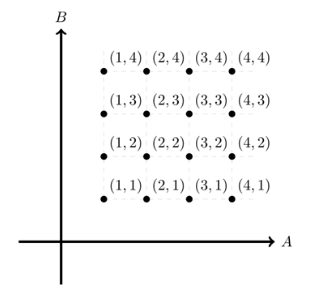

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

En esta parte del código se realiza la configuración básica del entorno de simulación y del robot.

Primero, se definen las características físicas del robot móvil: el tamaño de las ruedas y la distancia entre ellas. Luego, se establece con qué frecuencia se actualizará la simulación, lo que significa cada cuántos segundos se calcula una nueva posición del robot. Finalmente, se define la posición inicial del robot y se crea una matriz para almacenar cómo va cambiando su ubicación a lo largo del tiempo.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:39;        % Time array

% Initial conditions
initPose = [12;2;45];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load complexMap

Crea un sensor virtual llamado **lidar**, que simula un láser giratorio. Este sensor permite detectar la distancia entre el robot y los objetos que lo rodean. Se define el rango del sensor (hasta dónde puede “ver”) y los ángulos en los que realiza las mediciones, que en este caso abarcan todo el entorno en 360 grados

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,250);%51
lidar.maxRange = 2;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

En esta sección, se definen los waypoints  y se configuran dos controladores: uno para seguir la ruta y otro para evitar obstáculos.

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 12,9.5 ;  12,7 ; 12,5; 8.5,5;8.5,2;...
                       6,2 ; 8.5,7; 8.5,9.5; 6,9.5; 3,9.5 ;3,7;...
                       6,7 ; 6,5; 3,5 ;3,2];


Luego, se configura el **controlador de persecución pura (Pure Pursuit)**, que guía al robot hacia el siguiente punto en la ruta. Este controlador ajusta el movimiento del robot dependiendo de su posición actual y de la ubicación del siguiente punto a alcanzar.

% Pure Pursuit Controller
% Lista de puntos (coordenadas x, y) que el robot debe seguir
controller = controllerPurePursuit;
controller.Waypoints = waypoints;

% Distancia mínima que el robot usa para buscar su siguiente punto objetivo
controller.LookaheadDistance = .5;%0.5

% 	Velocidad lineal deseada para el robot
controller.DesiredLinearVelocity = 1.5; %0.75

%Máxima velocidad angular permitida para girar
controller.MaxAngularVelocity = 20; %20


Se configura un segundo controlador llamado **VFH (Vector Field Histogram)**, que se usa para evitar obstáculos. Este controlador analiza los datos del sensor lidar y determina hacia qué dirección el robot puede avanzar sin chocar. Se le indican parámetros como el tamaño del robot, la distancia mínima segura a obstáculos y qué tan lejos debe mirar el sensor.

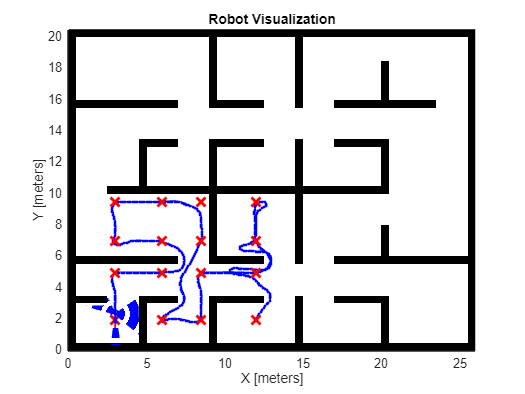

% Vector Field Histogram (VFH) for obstacle avoidance
% Objeto que arepresenta el controlador VFH para evitar obstáculos.
vfh = controllerVFH;
% Rango mínimo y máximo que considera el sensor para detectar objetos.
vfh.DistanceLimits = [0.05 3]; %0.05 3
% Resolución angular del análisis del entorno.
vfh.NumAngularSectors = 900; %36

% Valores que definen qué tan cerca debe estar un obstáculo para ser considerado.
vfh.HistogramThresholds = [3 8]; % 5y 10
% Radio aproximado del robot, usado para evitar colisiones
vfh.RobotRadius = L*.15;
% Distancia adicional de seguridad respecto a los obstáculos.
vfh.SafetyDistance = L*.15;

% Radio mínimo de giro que puede realizar el robot.
vfh.MinTurningRadius = .1;%0.25



%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = atan2(lookAheadPt(2)-curPose(2),lookAheadPt(1)-curPose(1)) - curPose(3);
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.1
        wRef = 5*steerDir;
    end
    
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end